# Metoda celor mai mici patrate

Dandu-se punctele 

(0, -4), (1, 0), (2, 4), (3, -2) 

determinati polinomul de gradul I corespunzator acestor date prin metoda celor mai mici patrate.

x=0:3;
y=[-4,0,4,-2];

Construim design matrix si determinam coeficientii

X=[ones(4,1),x'];
c=X\y'

c =    -2.0000
    1.0000


Reprezentam grafic punctele si aproximanta

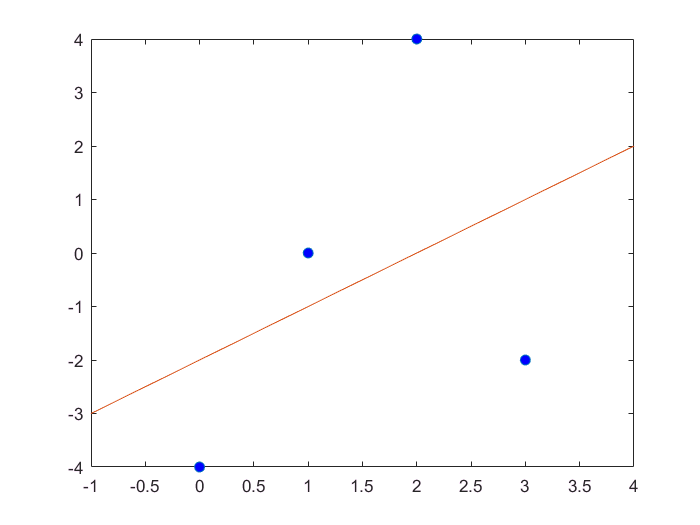

t=linspace(-1,4,10);
ty=c(1)+c(2)*t;
plot(x,y,'o',t,ty,'MarkerFaceColor','blue')

Ecuatiile normale

B=X'*X

B =      4     6
     6    14


X'*y'

ans =     -2
     2


[Q,R]=qr(X)

Q =    -0.5000    0.6708    0.0236    0.5472
   -0.5000    0.2236   -0.4393   -0.7120
   -0.5000   -0.2236    0.8079   -0.2176
   -0.5000   -0.6708   -0.3921    0.3824


R =    -2.0000   -3.0000
         0   -2.2361
         0         0
         0         0


[Q2,R2]=qr(X,0)